% Test file for "funPtInTriCheck" to check points inside or outside a given 2D triangle 
% -----------------------------------------------
% Author: Jin Yang (jyang526@wisc.edu)
% Date: 07-07-2020
%
% References
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all; clear; clc; clearvars -global

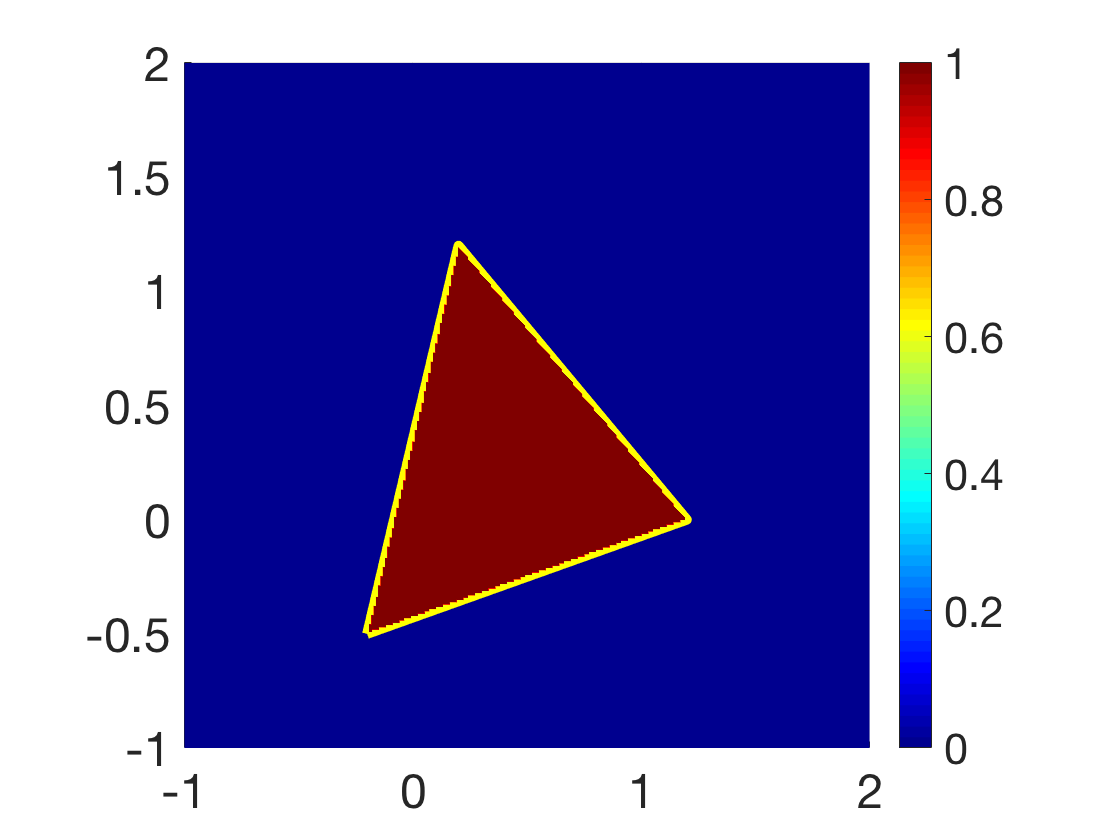

%% ====================================
% Example 1: 2D case
% ====================================
TriNodeCoord = [-0.2, -0.5; 0.2, 1.2; 1.2, 0];

[ptx,pty] = meshgrid([-1:0.01:2, -1:0.01:2]);
PtToCheckCoord = [ptx(:),pty(:)];

ptInTriOrNot = funPtInTriCheck(TriNodeCoord,PtToCheckCoord);
% This code also works but slow:  ptInTriOrNot = funPtInTriCheckNd(TriNodeCoord,PtToCheckCoord);
 
% ====== Plot ======
ptInTriOrNot = reshape(ptInTriOrNot,size(ptx));
figure, surf(ptx,pty, double(ptInTriOrNot),'edgecolor','none','facecolor','interp' );
view([0,90]); axis equal; set(gca,'fontsize',24); axis tight; colorbar; colormap jet;

hold on, plot(TriNodeCoord([1,2,3,1]',1),TriNodeCoord([1,2,3,1]',2),'y-','linewidth',5);

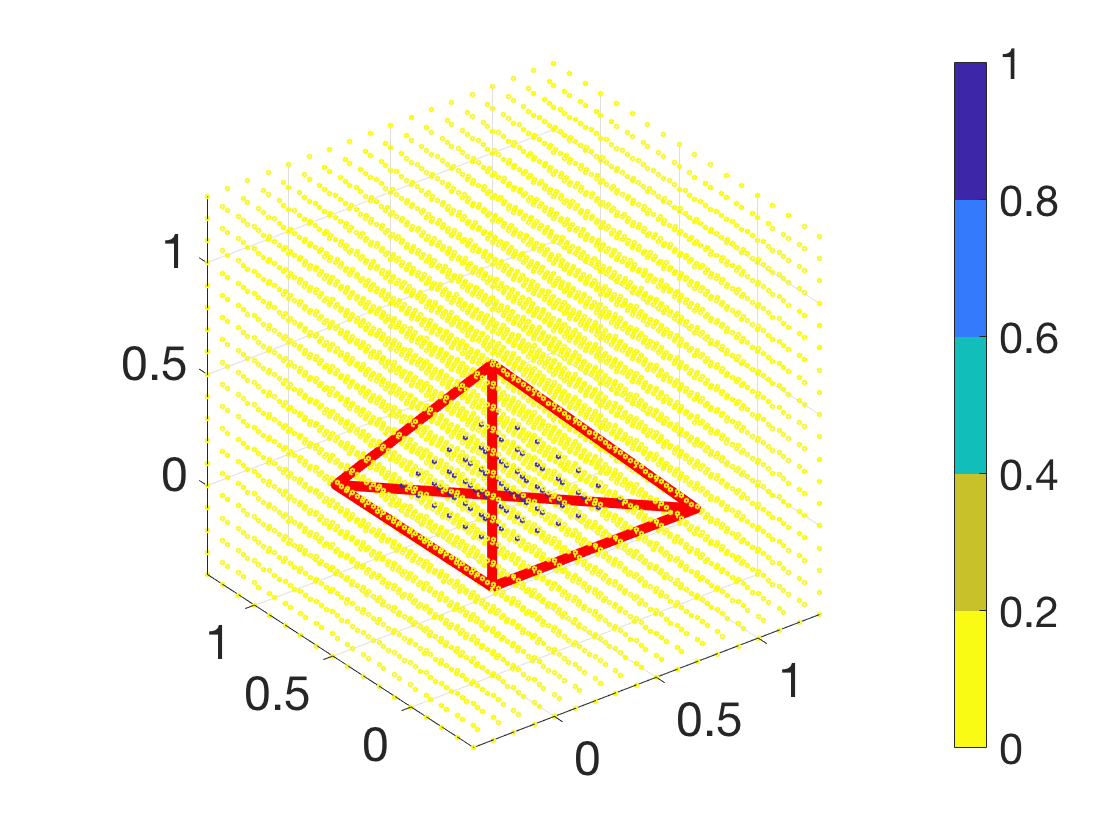

%% ====================================
% Example 2: 3D case or arbitrary dimension case
% ====================================
TriNodeCoord3 = [0,0,0;  1,0,0; 0,1,0; 0,0,1];

[ptx3,pty3,ptz3] = meshgrid([-0.4:0.1:1.3, -0.4:0.1:1.3, -0.4:0.1:1.3]);
PtToCheckCoord3 = [ptx3(:),pty3(:),ptz3(:)];

ptInTriOrNot3 = funPtInTriCheckNd(TriNodeCoord3,PtToCheckCoord3);

% ====== Plot ======
 
figure, scatter3(ptx3(:),pty3(:),ptz3(:), 4*ones(length(ptx3(:)),1), double(ptInTriOrNot3(:))  );
axis equal; set(gca,'fontsize',24); axis tight; colormap(flipud(parula(5))); colorbar;  

hold on, plot3(TriNodeCoord3([1,2,3,4,1]',1),TriNodeCoord3([1,2,3,4,1]',2),TriNodeCoord3([1,2,3,4,1]',3 ),'r-','linewidth',5);
hold on, plot3(TriNodeCoord3([1,3]',1),TriNodeCoord3([1,3]',2),TriNodeCoord3([1,3]',3 ),'r-','linewidth',5);
hold on, plot3(TriNodeCoord3([2,4]',1),TriNodeCoord3([2,4]',2),TriNodeCoord3([2,4]',3 ),'r-','linewidth',5);